## CAPTCHA Project

### Pipeline

- Image Acquisition

- Preprocessing + Enhancement

- Segmentation

- Feature Extraction + Description

- Classification + Interpretation + Recognition

- Result

### **Data Considerations**

- Repeat diagonal wave pattern

- Foreground area of interest

- Object rotation

- Object overlap

- Object misalignment

- Gaussian type noise

- Line noise

- Varying levels of blur

- Different noise per colour channel

### Solution Considerations

- Training vs. Testing data split to measure generalization

- Need to avoid overfitting

- Versioning

## Acquisition

Want to sample from training data:

- dataset 1200 images + 1 label-file

- 80/20 training/eval

% get list of image files
image_files = dir('Train/captcha_*.png');
total_num_images = length(image_files); 
% partition random subset 80% of all images
selected_num_images = (0.8)*total_num_images;
selected_images = image_files(randperm(total_num_images, selected_num_images));

selected_images = 960x1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


% get file names of selection
selected_images_cellarray = struct2cell(selected_images);
frozen_selection = selected_images_cellarray(1,:);

Variable **frozen_selection** is an array of pre-selected image files.

% load one image: 325 x 435 x (RGB) uint8 
% im2double rescales from integer to range [0, 1] double
idx = 1;
test_image = im2double(imread(sprintf('Train/%s', frozen_selection{idx})));
% is it worth resizing to square? imresize(test_image,[128 128],"nearest");
% nyquist frequency, maximum frequency expressible
test_image_dims = size(test_image,1:2);
test_image_nyquist = floor(test_image_dims ./ 2);
% channels r, g, b, and grayscale variant
[test_r,test_g,test_b] = imsplit(test_image);
test_gs = im2gray(test_image);

Variables **test_image**, **test_r** , **test_g** , **test_b** and **test_gs** contain Source, R, G, B, Grayscale respectively. 

### Preprocess and Enhance

Lipstick on pig

#### Define some utility functions

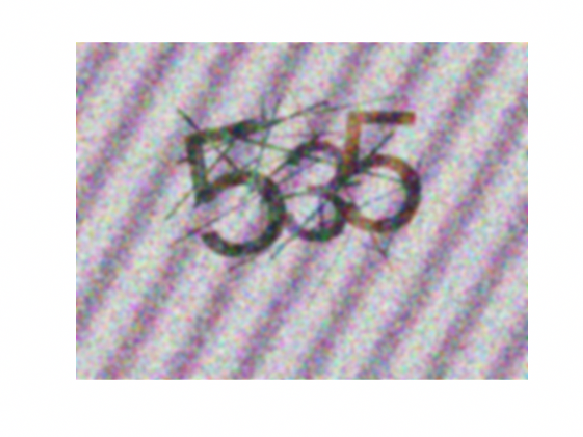

% utility functions for fft of image
function result_fft = forward_fft(src_image)
% forward fft transform
    I = src_image;
    result_fft = fftshift(fft2(I));
end
function result = disp_fft(src_fft)
% rescaled log magnitude in freq domain to [0,1]

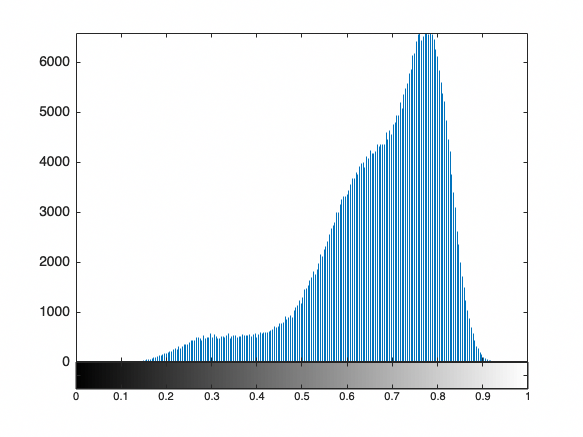

    F = src_fft;

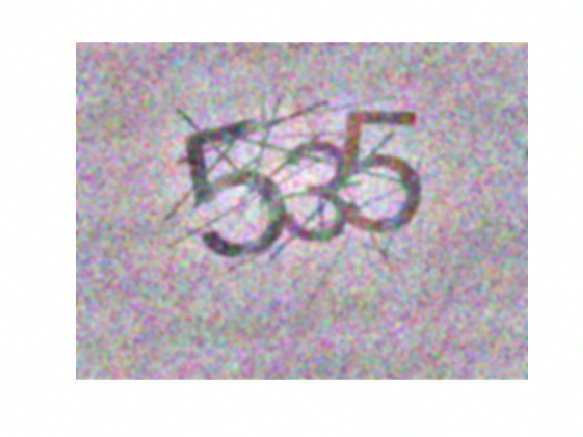

    result = mat2gray(log(abs(F)));
end

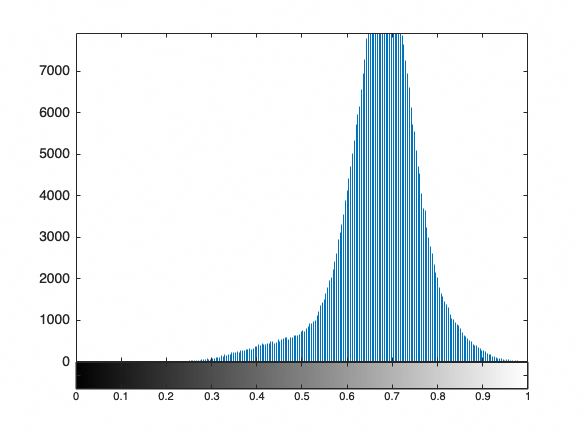

function result_image = backward_fft(src_fft)

% backward fft transform
    F = src_fft;
    result_image = ifft2(ifftshift(F));
end
function result_fft = spec_filter_fft(src_fft, LOW, HIGH)
% mixed low-high-bandpass filter,
% interesting results when exponent (ex) > 1 
% suppresses mean frequency and reveals outliers
    ex = 1; 
    d_fft = disp_fft(src_fft).^(ex);
    d_mask = ~((d_fft>LOW)&(d_fft<HIGH));
    result_fft = src_fft.*d_mask;
end
function result_image = spec_filter_image(src_image, LOW, HIGH)
    % filter frequency bands of an image; 
    % good defaults are LOW=0.75, HIGH=0.90
    result_image = real(backward_fft(spec_filter_fft(forward_fft(src_image),LOW,HIGH)));
end

Usage like, **forward_fft** --> **spec_filter_fft** --> **backward_fft** (low/high pass filter based on extrema, can use exp in fourier domain to extrude)

or **forward_fft** --> **disp_fft** --> **imshow **(to find artifacts)

#### Actual preprocessing

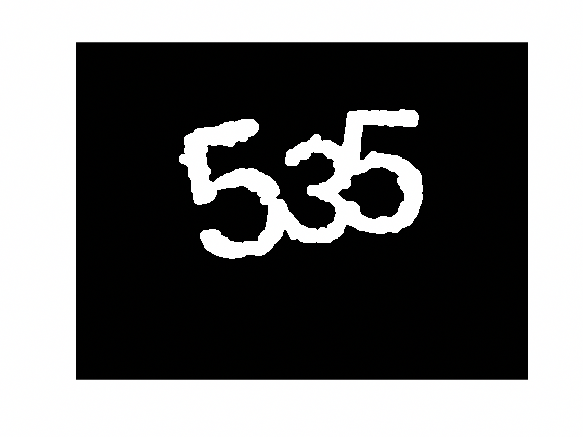

% apply bandpass filter to remove repeat/wave patterns
test_image_spec = spec_filter_image(test_image,0.75,0.9);

% sample background space
test_bg_sample = imcrop(test_image_spec,[1 1 20 20]);

% compare before/after bandpass filter
imshow(test_image)

imhist(test_image)

imshow(test_image_spec)
imhist(test_image_spec)

% dark spots defined by fewer colours
test_image_min_gs = im2gray(min(test_image_spec,[],3));

% median stuff
test_image_median = uint8(zeros(size(test_image_spec)));
test_image_uint8 = im2uint8(test_image_spec);
for i = 1:3
    test_image_median(:,:,i) = medfilt2(test_image_uint8(:,:,i), [5 5]); % Noise removal
end

% this seems to work better without median if using FFT?
% A ====
test_image_gray = im2gray(im2double(test_image_median));
test_image_bin = ~imbinarize(test_image_gray, graythresh(test_image_gray));

% changed dilate to disk-5
A = imdilate(bwareaopen(imerode(test_image_bin, strel('disk',4)), 300), strel('disk', 5));

% B ====
test_image_gray = im2gray(test_image_min_gs);
test_image_bin = ~imbinarize(test_image_gray, graythresh(test_image_gray));

% changed dilate to disk-5
B = imdilate(bwareaopen(imerode(test_image_bin, strel('disk',4)), 300), strel('disk', 5));

imshow(B)

### Segment

Cut up some stuff

% ccomponents
cc = bwconncomp(B, 4);

d1 = 145x78 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

props = regionprops(cc, 'Image');

% Step 3: Handle different numbers of components
if cc.NumObjects == 1
    [m, n] = size(props(1).Image);
    split = round(n / 3);
    d1 = imcrop(props(1).Image, [0 0 split m]);
    d2 = imcrop(props(1).Image, [split 0 split m]);
    d3 = imcrop(props(1).Image, [2*split 0 split m]);
elseif cc.NumObjects == 2
    % Split the wider component into two parts
    [m1, n1] = size(props(1).Image);
    [m2, n2] = size(props(2).Image);
    if n1 > n2
        d1 = imcrop(props(1).Image, [0 0 round(n1/2) m1]);
        d2 = imcrop(props(1).Image, [round(n1/2) 0 round(n1/2) m1]);
        d3 = props(2).Image;
    else
        d1 = props(1).Image;
        d2 = imcrop(props(2).Image, [0 0 round(n2/2) m2]);
        d3 = imcrop(props(2).Image, [round(n2/2) 0 round(n2/2) m2]);
    end
elseif cc.NumObjects >= 3
    d1 = props(1).Image;
    d2 = props(2).Image;
    d3 = props(3).Image;
else
    return; % If no components are detected, FeatMat remains zeros(3,15)
end


### Feature Extract

Check about the things

#### Define Utils

function F = ShapeFeats(S)
    % seems Euler and Circularity get mixed up wrt 3/5
    % but Hu-moments capture invariants
    %fts = {'Circularity', 'Area', 'EulerNumber', 'Centroid', 'Solidity', 'Eccentricity'}; 
    fts = {'Area', 'Centroid', 'Solidity', 'Eccentricity'}; 
    Ft = regionprops('Table', S, fts{:});
    if ~isempty(Ft)
        [~, idx] = max(Ft.Area);
        F = [Ft{idx,:}];
    else
        F = zeros(1, 4); % Return zeros if no shape features are detected
    end
end

#### Do Extract

FeatMat(1,:) = [ShapeFeats(d1), hu_moments(d1)];
FeatMat(2,:) = [ShapeFeats(d2), hu_moments(d2)];
FeatMat(3,:) = [ShapeFeats(d3), hu_moments(d3)];